# EOG Filter VEOG and HEOG R12 for S5S6 Trial 1

Setup the path and load data from the .vhdr file

Using a specific interval

clearvars; close all; clc;

addpath(genpath('Bali_Data_and_Codes'));
if ~exist('pop_loadbv','file'), eeglab; close; end

filePath = 'C:\Users\jvela\Downloads\BGBMB - Rehearsal 12 (4 Jul, 2024)\BGBMB - Rehearsal 12 (4 Jul, 2024)'; 
fileName = '20240704_R12_S5S6_EEG_Run2.vhdr';

% Trial 1
target_interval = [ 1568881 1998272];

Load and print the EOG channels for each subject

EEG_S5 = pop_loadbv(filePath, fileName, target_interval, [1:32]);

pop_loadbv(): reading header file
Done.
pop_loadbv(): reading EEG data
The header file points to a binary file that does not exist
trying to open a binary file with the same name as the header
file and a different extension...
Binary file is truncated/incomplete
pop_loadbv(): scaling EEG data
pop_loadbv(): reading marker file
Done.
pop_loadbv() warning: data files in header and marker files inconsistent.


EEG_S6 = pop_loadbv(filePath, fileName, target_interval, [33:64]);

pop_loadbv(): reading header file
Done.
pop_loadbv(): reading EEG data
The header file points to a binary file that does not exist
trying to open a binary file with the same name as the header
file and a different extension...
Binary file is truncated/incomplete
pop_loadbv(): scaling EEG data
pop_loadbv(): reading marker file
Done.
pop_loadbv() warning: data files in header and marker files inconsistent.



disp('Channels for S5:');

Channels for S5:


disp({EEG_S5.chanlocs.labels}'); 

    {'1' }
    {'2' }
    {'3' }
    {'4' }
    {'5' }
    {'6' }
    {'7' }
    {'8' }
    {'9' }
    {'10'}
    {'11'}
    {'12'}
    {'13'}
    {'14'}
    {'15'}
    {'16'}
    {'17'}
    {'18'}
    {'19'}
    {'20'}
    {'21'}
    {'22'}
    {'23'}
    {'24'}
    {'25'}
    {'26'}
    {'27'}
    {'28'}
    {'29'}
    {'30'}
    {'31'}
    {'32'}



disp('Channels for S6:');

Channels for S6:


disp({EEG_S6.chanlocs.labels}');

    {'33'}
    {'34'}
    {'35'}
    {'36'}
    {'37'}
    {'38'}
    {'39'}
    {'40'}
    {'41'}
    {'42'}
    {'43'}
    {'44'}
    {'45'}
    {'46'}
    {'47'}
    {'48'}
    {'49'}
    {'50'}
    {'51'}
    {'52'}
    {'53'}
    {'54'}
    {'55'}
    {'56'}
    {'57'}
    {'58'}
    {'59'}
    {'60'}
    {'61'}
    {'62'}
    {'63'}
    {'64'}



Extract index for EOG channels

s5_L_idx = 31; 
s5_R_idx = 32;
s6_L_idx = 31; 
s6_R_idx = 32;
v_top_idx = 15; 
v_bot_idx = 20;

Calculate the Bipolar Derivation **HEOG and VEOG**

heog_s5_raw = double(EEG_S5.data(s5_L_idx, :) - EEG_S5.data(s5_R_idx, :));
veog_s5_raw = double(EEG_S5.data(v_top_idx, :) - EEG_S5.data(v_bot_idx, :));

heog_s6_raw = double(EEG_S6.data(s6_L_idx, :) - EEG_S6.data(s6_R_idx, :));
veog_s6_raw = double(EEG_S6.data(v_top_idx, :) - EEG_S6.data(v_bot_idx, :));

Constants

fs = EEG_S5.srate;                 
N = length(heog_s5_raw);           
t = (0:N-1) / fs;

Butterworth Filter 4th order

`butter` function generates a **Butterworth filter**. This is a recursive filter, meaning it uses its own previous output to calculate the next output (feedback)

b: feedforward

a: feedback

*FIR (Finite Impulse Response) filters use only current and past input samples for output, while IIR (Infinite Impulse Response) filters also use past output samples, allowing for more complex filtering with fewer coefficients. FIR filters are generally more stable and have a linear phase response, whereas IIR filters can be more efficient but may face stability issues*

low_cut = 0.1;      
high_cut = 30;      
filter_order = 4;   

[z, p, k] = butter(filter_order, [low_cut high_cut]/(fs/2), 'bandpass');
[sos, g] = zp2sos(z, p, k);

Zero Phase Filtering to cancel time delay

heog_s5_clean = filtfilt(sos, g, heog_s5_raw);
veog_s5_clean = filtfilt(sos, g, veog_s5_raw);

heog_s6_clean = filtfilt(sos, g, heog_s6_raw);
veog_s6_clean = filtfilt(sos, g, veog_s6_raw);

Plot raw signals for the whole time period

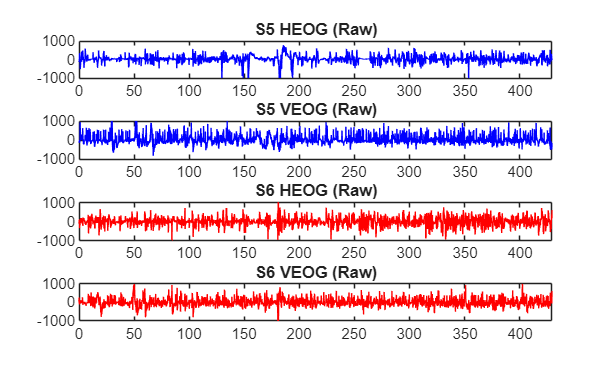

figure('Color','w', 'Name', 'Full Raw Signals'); ylabel('Amplitude (\muV)'); xlabel('Time (s)');
standard_limit = 1000;
ylim_standard = [-standard_limit, standard_limit];
subplot(4,1,1); plot(t, heog_s5_raw, 'b'); title('S5 HEOG (Raw)'); xlim([0 max(t)]); ylim(ylim_standard);
subplot(4,1,2); plot(t, veog_s5_raw, 'b'); title('S5 VEOG (Raw)'); xlim([0 max(t)]); ylim(ylim_standard);
subplot(4,1,3); plot(t, heog_s6_raw, 'r'); title('S6 HEOG (Raw)'); xlim([0 max(t)]); ylim(ylim_standard); 
subplot(4,1,4); plot(t, veog_s6_raw, 'r'); title('S6 VEOG (Raw)'); xlim([0 max(t)]); ylim(ylim_standard); 

Plot filtered signals vs raw signals for comparision

Add time_axis(idx) for only zooming into a window

Leave 't' alone for the whole time

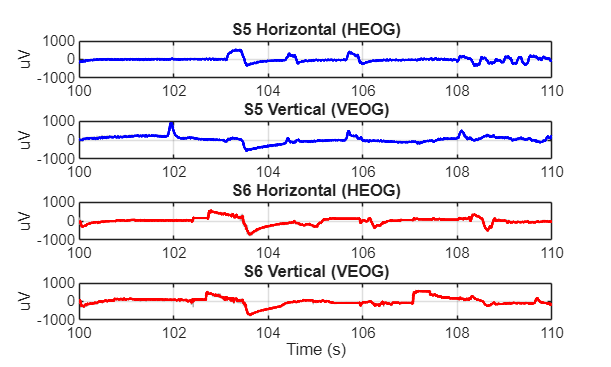

time_axis = t;
window_sec = 100:110; % choosen window
idx = round(window_sec(1)*fs) : round(window_sec(end)*fs);
zoom_ylim = [-1000 1000];
zoom_xlim = [100 110];
figure('Color','w', 'Name', 'Filtered Signals VEOG and HEOG');

subplot(4,1,1);
plot(time_axis(idx), heog_s5_raw(idx), 'Color', [0.7 0.7 0.7]); hold on;
plot(time_axis(idx), heog_s5_clean(idx), 'b', 'LineWidth', 1.5);
title('S5 Horizontal (HEOG)'); ylabel('uV'); grid on; xlim(zoom_xlim); ylim(zoom_ylim);

subplot(4,1,2);
plot(time_axis(idx), veog_s5_raw(idx), 'Color', [0.7 0.7 0.7]); hold on;
plot(time_axis(idx), veog_s5_clean(idx), 'b', 'LineWidth', 1.5);
title('S5 Vertical (VEOG)'); ylabel('uV'); grid on; xlim(zoom_xlim); ylim(zoom_ylim);

subplot(4,1,3);
plot(time_axis(idx), heog_s6_raw(idx), 'Color', [0.7 0.7 0.7]); hold on;
plot(time_axis(idx), heog_s6_clean(idx), 'r', 'LineWidth', 1.5);
title('S6 Horizontal (HEOG)'); ylabel('uV'); grid on; xlim(zoom_xlim); ylim(zoom_ylim); 

subplot(4,1,4);
plot(time_axis(idx), veog_s6_raw(idx), 'Color', [0.7 0.7 0.7]); hold on;
plot(time_axis(idx), veog_s6_clean(idx), 'r', 'LineWidth', 1.5);
title('S6 Vertical (VEOG)'); ylabel('uV'); grid on; xlim(zoom_xlim); ylim(zoom_ylim); xlabel('Time (s)');

Marker annotation on complete clean signal for the whole time period

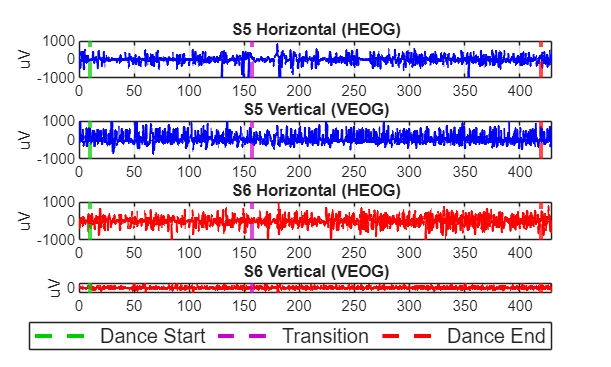

figure('Color','w', 'Name', 'Filtered Signals Only (Clean)');
zoom_ylim = [-1000 1000];

events = {
    1578881, 'Dance Start',              [0 0.8 0];   % Green
    1725881, 'Transition',               [0.8 0 0.8]; % Magenta
    1988272, 'Dance End',                [1 0 0]      % Red
};

current_interval_start = target_interval(1); 

for sp = 1:4
    subplot(4,1,sp);
    
    if sp == 1, data_clean = heog_s5_clean; title_str = 'S5 Horizontal (HEOG)';
    elseif sp == 2, data_clean = veog_s5_clean; title_str = 'S5 Vertical (VEOG)';
    elseif sp == 3, data_clean = heog_s6_clean; title_str = 'S6 Horizontal (HEOG)';
    elseif sp == 4, data_clean = veog_s6_clean; title_str = 'S6 Vertical (VEOG)'; xlabel('Time (s)');
    end
    
    if sp <= 2
        line_color = 'b';
    else
        line_color = 'r';
    end
    
    plot(t, data_clean, line_color, 'LineWidth', 1.2); hold on; 
    
    title(title_str); ylabel('uV'); grid on;
    xlim([0 max(t)]); ylim(zoom_ylim);
    
    for i = 1:size(events,1)
        event_sec = (events{i,1} - current_interval_start) / fs;
        xline(event_sec, '--', 'Color', events{i,3}, 'LineWidth', 2);
    end
end

h = zeros(size(events,1), 1); 
for i = 1:size(events,1)
    h(i) = plot(NaN, NaN, '--', 'Color', events{i,3}, 'LineWidth', 2);
end

lgd = legend(h, events(:,2), 'Orientation', 'horizontal', 'Location', 'southoutside');
lgd.FontSize = 10;
lgd.Box = 'on';

Zoom into marker zones to obtain 3 graphs

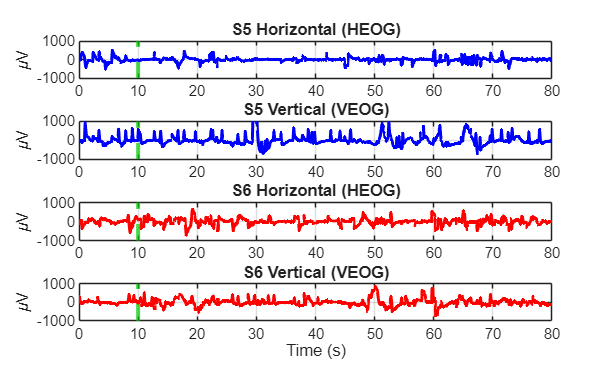

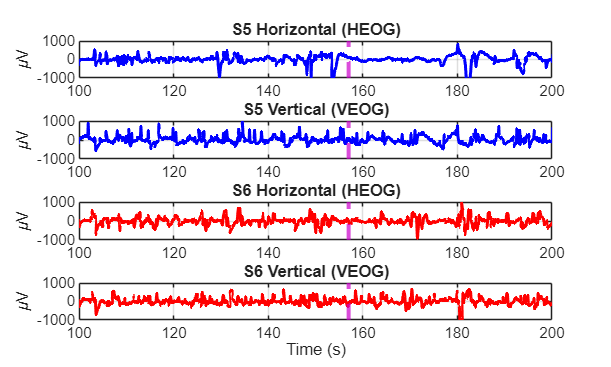

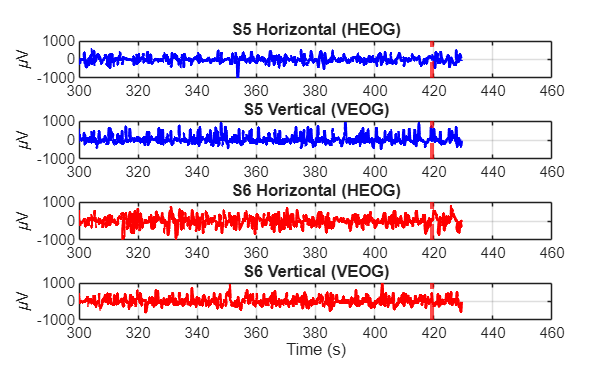

zoom_settings = {
    0,   80,  'Zoom 1: Dance Start (0-80s)';
    100, 200, 'Zoom 2: Transition (100-200s)';
    300, 460, 'Zoom 3: End Sequence (400-430s)'
};

for z = 1:size(zoom_settings, 1)
    z_start = zoom_settings{z, 1};
    z_end   = zoom_settings{z, 2};
    z_title = zoom_settings{z, 3};
    
    figure('Color','w', 'Name', z_title);
    
    for sp = 1:4
        subplot(4,1,sp);
        
        if sp == 1
            data = heog_s5_clean; 
            t_str = 'S5 Horizontal (HEOG)'; 
            col = 'b';
        elseif sp == 2
            data = veog_s5_clean; 
            t_str = 'S5 Vertical (VEOG)'; 
            col = 'b';
        elseif sp == 3
            data = heog_s6_clean; 
            t_str = 'S6 Horizontal (HEOG)'; 
            col = 'r';
        elseif sp == 4
            data = veog_s6_clean; 
            t_str = 'S6 Vertical (VEOG)'; 
            col = 'r';
        end
        
        plot(t, data, col, 'LineWidth', 1.5); hold on;
        ylabel('\muV');
        title(t_str);
        
        if sp == 4
            xlabel('Time (s)');
        end
        
        xlim([z_start z_end]);
        ylim([-1000 1000]);
        grid on;
        
        for i = 1:size(events,1)
            event_sec = (events{i,1} - current_interval_start) / fs;
            if event_sec >= z_start && event_sec <= z_end
                xline(event_sec, '--', 'Color', events{i,3}, 'LineWidth', 2);
            end
        end
    end
end

Z-score Thresholding to find blinks

- Apply a bandpass filter from 0.5 to 10 Hz

- Apply zero phase filtering

- Convert voltage to standard deviation because we can't apply a single threshold to all

- Catch absolute value because blinks can be positive or negative

- 3 sigma rule because 99.7% of data points fall within ±3 standard deviations in a normal distribution

- Apply a mask to then move on with saccades

subjects = {'S5', 'S6'};
metrics = struct();
fs = 1000;

for s = 1:2
    subj = subjects{s};
    
    if strcmp(subj, 'S5')
        h_data = heog_s5_clean(:); 
        v_data = veog_s5_clean(:);
    else
        h_data = heog_s6_clean(:);
        v_data = veog_s6_clean(:);
    end
    
    % Filter specifically to find blink "bumps" (0.5 - 10 Hz)
    [b_blink, a_blink] = butter(2, [0.5 10]/(fs/2));
    v_blink_temp = filtfilt(b_blink, a_blink, double(v_data));
    
    % Normalize to Z-Score (Standard Deviations)
    v_z = (v_blink_temp - mean(v_blink_temp)) / std(v_blink_temp);
    
    % Detect Peaks > 3 Std Devs
    [~, locs] = findpeaks(abs(v_z), 'MinPeakHeight', 3, 'MinPeakDistance', 0.2*fs);
    
    % Create Blink Mask (-100ms to +150ms around peak)
    blink_mask = false(size(v_data));
    win_pre = round(0.1 * fs); 
    win_post = round(0.15 * fs);
    
    for k = 1:length(locs)
        p_start = max(1, locs(k) - win_pre);
        p_end   = min(length(v_data), locs(k) + win_post);
        blink_mask(p_start:p_end) = true;
    end
    
    

Subject S5 (Hybrid): Found 183 Blinks (Z-Score) and 75 Saccades (I-VT).
Subject S6 (Hybrid): Found 85 Blinks (Z-Score) and 140 Saccades (I-VT).


I-VT Threshold to find Saccades

- Calculate point-to-point velocities for each point in the protocol

- Smooth

- Label each point below velocity threshold as a fixation point, otherwise as a saccade point

**It uses a FIR filter**

    vx = [0; diff(h_data)] * fs; 
    vy = [0; diff(v_data)] * fs; 
    vel_raw = sqrt(vx.^2 + vy.^2);
    
    vel_smooth = smoothdata(vel_raw, 'gaussian', 20);
    
    clean_velocity = vel_smooth(~blink_mask); 
    vt_thresh = mean(clean_velocity) + (5 * std(clean_velocity));

    saccade_mask = (vel_smooth > vt_thresh) & (~blink_mask);
    fixation_mask = (vel_smooth <= vt_thresh) & (~blink_mask);
    

Measure properties and metrics

    % 1. Blinks

SACCADES:


    edges_b = diff([0; blink_mask; 0]);

  S5 Count: 75 | Rate: 0.17 Hz


    metrics.(subj).Blinks.Starts = find(edges_b == 1);

  S6 Count: 140 | Rate: 0.33 Hz


    metrics.(subj).Blinks.Ends   = find(edges_b == -1) - 1;

----------------------------------------


    
    % 2. Saccades
    edges_s = diff([0; saccade_mask; 0]);
    metrics.(subj).Saccades.Starts = find(edges_s == 1);
    metrics.(subj).Saccades.Ends   = find(edges_s == -1) - 1;
    metrics.(subj).Saccades.VelocityTrace = vel_smooth;

FIXATIONS:


  S5 Count: 257


    % 3. Fixations

  S6 Count: 219


    edges_f = diff([0; fixation_mask; 0]);

----------------------------------------


    metrics.(subj).Fixations.Starts = find(edges_f == 1);
    metrics.(subj).Fixations.Ends   = find(edges_f == -1) - 1;

    % 4. Measure Saccade Properties
    num_sac = length(metrics.(subj).Saccades.Starts);
    metrics.(subj).Saccades.Amplitudes = zeros(num_sac, 1);
    metrics.(subj).Saccades.Durations  = zeros(num_sac, 1);
    metrics.(subj).Saccades.PeakVels   = zeros(num_sac, 1);

BLINKS:


  S5 Count: 183 | Rate: 25.57 blinks/min


    for k = 1:num_sac

  S6 Count: 82 | Rate: 11.46 blinks/min


        idx = metrics.(subj).Saccades.Starts(k) : metrics.(subj).Saccades.Ends(k);

        
        dx = h_data(idx(end)) - h_data(idx(1));
        dy = v_data(idx(end)) - v_data(idx(1));
        
        metrics.(subj).Saccades.Amplitudes(k) = sqrt(dx^2 + dy^2);
        metrics.(subj).Saccades.Durations(k)  = length(idx) / fs;
        metrics.(subj).Saccades.PeakVels(k)   = max(vel_smooth(idx));
    end
    
    % Measure Fixations
    num_fix = length(metrics.(subj).Fixations.Starts);
    metrics.(subj).Fixations.Durations = zeros(num_fix, 1);
    for k = 1:num_fix
        idx = metrics.(subj).Fixations.Starts(k) : metrics.(subj).Fixations.Ends(k);
        metrics.(subj).Fixations.Durations(k) = length(idx) / fs;

    end
    
    fprintf('Subject %s (Hybrid): Found %d Blinks (Z-Score) and %d Saccades (I-VT).\n', ...
        subj, length(locs), num_sac);
end

Box plot and raw stats for metric comparision

% Function to get rate (Hz)
get_rate = @(starts, total_dur) length(starts) / total_dur;

% Total duration of the recording (in seconds)

total_time_s5 = length(metrics.S5.Saccades.VelocityTrace) / fs;
total_time_s6 = length(metrics.S6.Saccades.VelocityTrace) / fs;

% --- SACCADES ---
count_s5 = length(metrics.S5.Saccades.Starts);
count_s6 = length(metrics.S6.Saccades.Starts);

rate_s5  = count_s5 / total_time_s5;
rate_s6  = count_s6 / total_time_s6;

fprintf('SACCADES:\n');
fprintf('  S5 Count: %d | Rate: %.2f Hz\n', count_s5, rate_s5);

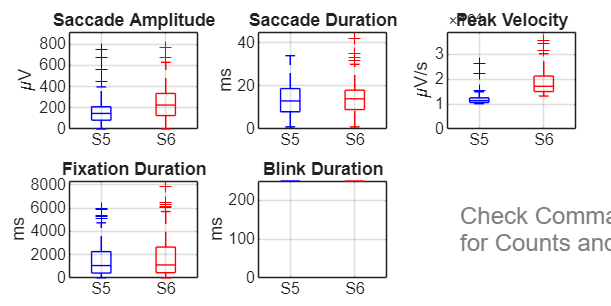

fprintf('  S6 Count: %d | Rate: %.2f Hz\n', count_s6, rate_s6);
fprintf('----------------------------------------\n');

% --- FIXATIONS ---

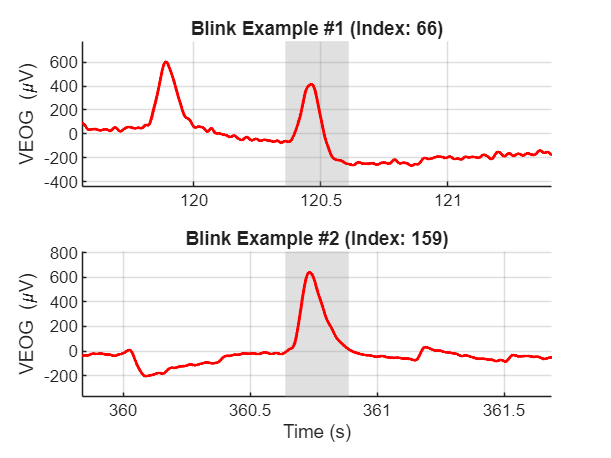

count_f5 = length(metrics.S5.Fixations.Starts);
count_f6 = length(metrics.S6.Fixations.Starts);

fprintf('FIXATIONS:\n');
fprintf('  S5 Count: %d\n', count_f5);
fprintf('  S6 Count: %d\n', count_f6);
fprintf('----------------------------------------\n');

% --- BLINKS ---
count_b5 = length(metrics.S5.Blinks.Starts);
count_b6 = length(metrics.S6.Blinks.Starts);
rate_b5  = count_b5 / total_time_s5 * 60; % Blinks per minute is standard
rate_b6  = count_b6 / total_time_s6 * 60;

fprintf('BLINKS:\n');
fprintf('  S5 Count: %d | Rate: %.2f blinks/min\n', count_b5, rate_b5);
fprintf('  S6 Count: %d | Rate: %.2f blinks/min\n', count_b6, rate_b6);
fprintf('========================================\n\n');


% 2. GENERATE DISTRIBUTION PLOTS
figure('Color', 'w', 'Name', 'Metric Distributions: S5 vs S6', 'Position', [100 100 1200 600]);
t = tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% Define Colors
c5 = [0.2 0.6 1]; 
c6 = [1 0.4 0.4]; 

% --- ROW 1: SACCADE METRICS ---
% 1. Amplitude
data_s5 = metrics.S5.Saccades.Amplitudes;
data_s6 = metrics.S6.Saccades.Amplitudes;
create_boxplot(nexttile, data_s5, data_s6, 'Saccade Amplitude', '\muV');

% 2. Duration
data_s5 = metrics.S5.Saccades.Durations * 1000; % ms
data_s6 = metrics.S6.Saccades.Durations * 1000;
create_boxplot(nexttile, data_s5, data_s6, 'Saccade Duration', 'ms');

% 3. Peak Velocity
data_s5 = metrics.S5.Saccades.PeakVels;
data_s6 = metrics.S6.Saccades.PeakVels;
create_boxplot(nexttile, data_s5, data_s6, 'Peak Velocity', '\muV/s');

% --- ROW 2: OTHER METRICS ---
% 4. Fixation Duration
data_s5 = metrics.S5.Fixations.Durations * 1000;
data_s6 = metrics.S6.Fixations.Durations * 1000;
create_boxplot(nexttile, data_s5, data_s6, 'Fixation Duration', 'ms');

% 5. Blink Duration
dur_b5 = (metrics.S5.Blinks.Ends - metrics.S5.Blinks.Starts) / fs * 1000;
dur_b6 = (metrics.S6.Blinks.Ends - metrics.S6.Blinks.Starts) / fs * 1000;
create_boxplot(nexttile, dur_b5, dur_b6, 'Blink Duration', 'ms');

% 6. Empty Tile (or simple text summary)
nexttile; axis off;
text(0.1, 0.5, {'Check Command Window', 'for Counts and Rates'}, 'FontSize', 12, 'Color', [0.5 0.5 0.5]);


% =========================================================================
% HELPER FUNCTION
% =========================================================================
function create_boxplot(ax, d5, d6, title_str, unit_str)
    if isempty(d5), d5 = NaN; end
    if isempty(d6), d6 = NaN; end

    % Combine
    group_ids = [repmat({'S5'}, length(d5), 1); repmat({'S6'}, length(d6), 1)];
    data_all = [d5; d6];

    boxplot(ax, data_all, group_ids, 'Colors', 'br', 'Symbol', '+');
    title(title_str);
    ylabel(unit_str);
    grid on;
    
    % Auto-zoom Y-axis (ignore extreme outliers > Q3 + 3*IQR)

    q3 = quantile(data_all, 0.75);
    iqr_val = iqr(data_all);
    upper_lim = q3 + 3 * iqr_val; 
    if ~isnan(upper_lim) && max(data_all) > upper_lim
        ylim([min(0, min(data_all)) upper_lim]);
    end
end

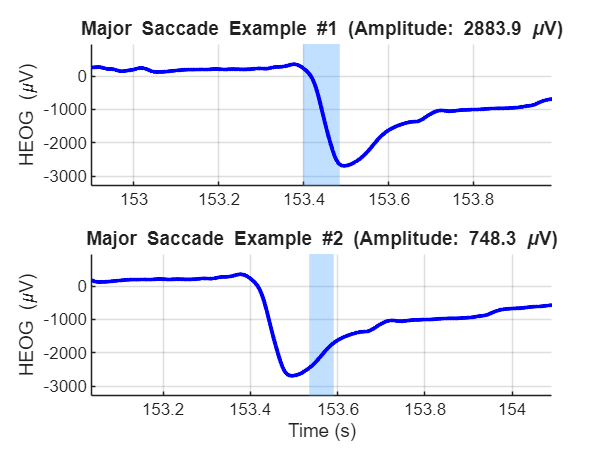

% --- STEP: PLOT RANDOMIZED PAIRED EXAMPLES (Wider View) ---

% 1. Setup Data
subj = 'S5';
if ~isfield(metrics, subj)
    error('Metrics for %s not found. Run the extraction step first.', subj);
end

h_sig = heog_s5_clean(:);
v_sig = veog_s5_clean(:);
t_full = (0:length(h_sig)-1) / fs;

% 2. Define Parameters (Updated for "Bigger Axes")
pad_sec = 0.8; % Increased from 0.4 to 0.8s for better context
pad_samp = round(pad_sec * fs);

% =========================================================================
% FIGURE 1: TWO RANDOM BLINKS (Vertical EOG)
% =========================================================================
evts = metrics.(subj).Blinks;
indices = find_random_valid_indices(evts, 2, length(h_sig), pad_samp);

figure('Color', 'w', 'Name', 'Random Blink Examples', 'Position', [50 100 800 600]);
tiledlayout(2, 1, 'TileSpacing', 'loose'); % 'loose' gives more room

for k = 1:2
    idx = indices(k);
    w_start = evts.Starts(idx) - pad_samp;
    w_end   = evts.Ends(idx) + pad_samp;
    range   = w_start:w_end;
    
    nexttile; hold on;
    plot(t_full(range), v_sig(range), 'r', 'LineWidth', 1.5);
    
    % Highlight
    e_start = t_full(evts.Starts(idx));
    e_end   = t_full(evts.Ends(idx));
    xregion(e_start, e_end, 'FaceColor', [0.6 0.6 0.6], 'FaceAlpha', 0.3);
    
    title(sprintf('Blink Example #%d (Index: %d)', k, idx));
    ylabel('VEOG (\muV)'); grid on; 
    
    % Add Y-Axis Margin
    axis tight;
    yl = ylim; 
    margin = (yl(2) - yl(1)) * 0.2; % 20% breathing room
    ylim([yl(1)-margin yl(2)+margin]);
    
    if k==2, xlabel('Time (s)'); end
end

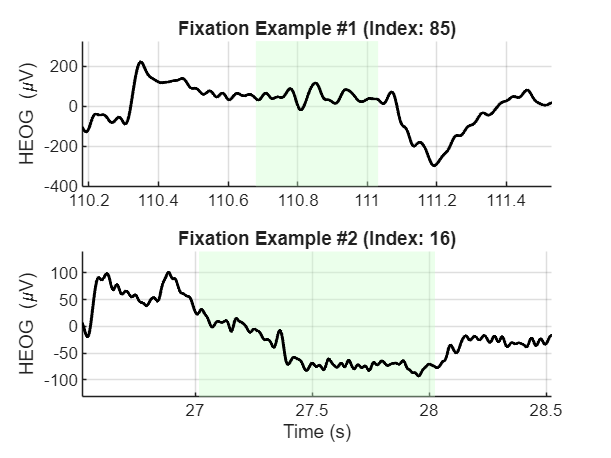


% --- STEP: PLOT LARGEST "TEXTBOOK" SACCADES ---
subj = 'S5';
h_sig = heog_s5_clean(:);
t_full = (0:length(h_sig)-1) / fs;
evts = metrics.(subj).Saccades;

% 1. Sort Saccades by Amplitude (Biggest first)
[sorted_amps, sort_idx] = sort(evts.Amplitudes, 'descend');

% 2. Pick the Top 2 (that aren't at the edge of the file)
top_indices = [];
pad_sec = 0.5; 
pad_samp = round(pad_sec * fs);

for k = 1:length(sort_idx)
    orig_idx = sort_idx(k);
    s = evts.Starts(orig_idx);
    e = evts.Ends(orig_idx);
    if (s - pad_samp > 1) && (e + pad_samp < length(h_sig))
        top_indices(end+1) = orig_idx; %#ok<AGROW>
    end
    if length(top_indices) >= 2, break; end
end

% 3. Plot
figure('Color', 'w', 'Name', 'Textbook Saccade Examples', 'Position', [100 100 800 600]);
tiledlayout(2, 1, 'TileSpacing', 'loose');

for k = 1:length(top_indices)
    idx = top_indices(k);
    
    % Define Window
    w_start = evts.Starts(idx) - pad_samp;
    w_end   = evts.Ends(idx) + pad_samp;

    range   = w_start:w_end;
    
    nexttile; hold on;
    % Plot Signal
    plot(t_full(range), h_sig(range), 'b', 'LineWidth', 2);
    
    % Highlight Saccade
    e_start = t_full(evts.Starts(idx));
    e_end   = t_full(evts.Ends(idx));
    xregion(e_start, e_end, 'FaceColor', [0.2 0.6 1], 'FaceAlpha', 0.3);
    
    % Labels
    amp = evts.Amplitudes(idx);
    title(sprintf('Major Saccade Example #%d (Amplitude: %.1f \\muV)', k, amp));
    ylabel('HEOG (\muV)'); grid on; axis tight;
    
    % Force nice Y-limits
    yl = ylim; margin = (yl(2)-yl(1))*0.2;
    ylim([yl(1)-margin yl(2)+margin]);
    
    if k==2, xlabel('Time (s)'); end
end

% =========================================================================
% FIGURE 3: TWO RANDOM FIXATIONS (Horizontal EOG)
% =========================================================================
evts = metrics.(subj).Fixations;
indices = find_random_valid_indices(evts, 2, length(h_sig), pad_samp);

figure('Color', 'w', 'Name', 'Random Fixation Examples', 'Position', [150 100 800 600]);
tiledlayout(2, 1, 'TileSpacing', 'loose');

for k = 1:2
    idx = indices(k);
    w_start = evts.Starts(idx) - pad_samp;
    w_end   = evts.Ends(idx) + pad_samp;
    range   = w_start:w_end;
    
    nexttile; hold on;
    plot(t_full(range), h_sig(range), 'k', 'LineWidth', 1.5);
    
    % Highlight
    e_start = t_full(evts.Starts(idx));
    e_end   = t_full(evts.Ends(idx));
    xregion(e_start, e_end, 'FaceColor', [0.8 1 0.8], 'FaceAlpha', 0.4);
    
    title(sprintf('Fixation Example #%d (Index: %d)', k, idx));
    ylabel('HEOG (\muV)'); grid on;
    
    % Add Y-Axis Margin
    axis tight;
    yl = ylim; 
    margin = (yl(2) - yl(1)) * 0.2;
    ylim([yl(1)-margin yl(2)+margin]);
    
    if k==2, xlabel('Time (s)'); end
end

% =========================================================================
% UPDATED HELPER FUNCTION (Random Selection)
% =========================================================================
function indices = find_random_valid_indices(evt_struct, count, data_len, padding)
    indices = [];
    found = 0;
    
    num_events = length(evt_struct.Starts);
    if num_events == 0
        warning('No events found for this category.');
        return;
    end
    
    % Create a RANDOM shuffle of all possible event indices
    random_order = randperm(num_events);
    
    for k = 1:num_events
        idx = random_order(k); % Pick random index
        
        s = evt_struct.Starts(idx);
        e = evt_struct.Ends(idx);
        
        % Check bounds (don't pick events at the very edges)
        if (s - padding > 1) && (e + padding < data_len)
            indices = [indices, idx]; %#ok<AGROW>
            found = found + 1;
        end
        
        if found >= count
            break;
        end
    end
    
    if found < count
        warning('Could not find enough valid events. Using whatever was found.');
    end
end

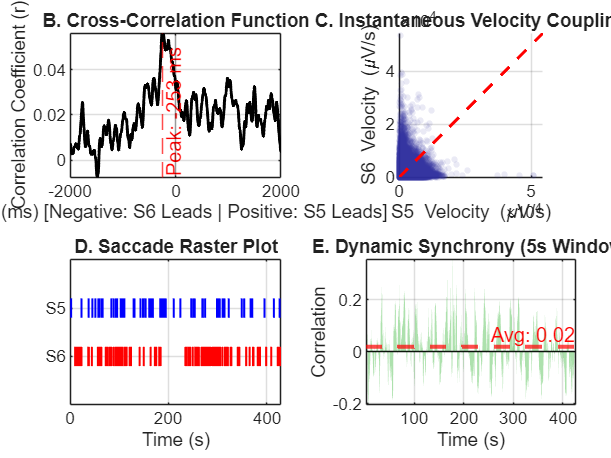



% --- SYNCHRONY VISUALIZATION SUITE ---
% Inputs: metrics structure, fs (sampling rate)

% 1. PREPARE DATA
v5 = metrics.S5.Saccades.VelocityTrace;
v6 = metrics.S6.Saccades.VelocityTrace;

% Truncate to matching length
min_len = min(length(v5), length(v6));
v5 = v5(1:min_len);
v6 = v6(1:min_len);
t = (1:min_len) / fs;

figure('Color', 'w', 'Name', 'Comprehensive Synchrony Analysis', 'Position', [50 50 1200 900]);
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% ---------------------------------------------------------
% PLOT B: CROSS-CORRELATION VS LAG (The "Gold Standard")
% ---------------------------------------------------------
nexttile;

% Calculate Cross-Correlation
max_lag_sec = 2.0; % Look +/- 2 seconds
max_lag = round(max_lag_sec * fs);
[r, lags] = xcorr(v5 - mean(v5), v6 - mean(v6), max_lag, 'coeff');
lags_ms = (lags / fs) * 1000; % Convert to milliseconds

plot(lags_ms, r, 'k', 'LineWidth', 1.5); hold on;

% Find and Mark the Peak
[max_r, idx] = max(r);
peak_lag = lags_ms(idx);
xline(peak_lag, 'r--', sprintf('Peak: %.0f ms', peak_lag), 'LabelVerticalAlignment', 'bottom');
xline(0, 'k-', 'Alpha', 0.3); % Center line

title('B. Cross-Correlation Function');
xlabel('Lag (ms) [Negative: S6 Leads | Positive: S5 Leads]');
ylabel('Correlation Coefficient (r)');
grid on; axis tight;
% Interpretation: A peak at 0 means perfect sync. A shift means one reacts to the other.

% ---------------------------------------------------------
% PLOT C: SCATTER PLOT (S5 vs S6 Velocity)
% ---------------------------------------------------------
nexttile;

% Downsample for performance (plot every 10th point)
ds = 10; 
scatter(v5(1:ds:end), v6(1:ds:end), 10, 'filled', 'MarkerFaceColor', [0.2 0.2 0.6], 'MarkerFaceAlpha', 0.1);
hold on;

% Add Diagonal Line (Perfect Sync Reference)
max_val = max([max(v5), max(v6)]);
plot([0 max_val], [0 max_val], 'r--', 'LineWidth', 1.5);

title('C. Instantaneous Velocity Coupling');
xlabel('S5 Velocity (\muV/s)');
ylabel('S6 Velocity (\muV/s)');
axis square; grid on;
xlim([0 max_val*0.8]); ylim([0 max_val*0.8]); 
% Interpretation: A diagonal "cigar" shape = Synchronized. A round blob = Independent.

% ---------------------------------------------------------
% PLOT D: EVENT-ALIGNED RASTER (Saccade Ticks)
% ---------------------------------------------------------
nexttile;

% Get Saccade Start Times (in seconds)
starts_s5 = metrics.S5.Saccades.Starts / fs;
starts_s6 = metrics.S6.Saccades.Starts / fs;

% Plot S5 Ticks (Top Row)
% We draw a small vertical line for every saccade
for i = 1:length(starts_s5)

    plot([starts_s5(i) starts_s5(i)], [1.8 2.2], 'b', 'LineWidth', 1); hold on;
end

% Plot S6 Ticks (Bottom Row)
for i = 1:length(starts_s6)
    plot([starts_s6(i) starts_s6(i)], [0.8 1.2], 'r', 'LineWidth', 1);
end

title('D. Saccade Raster Plot');
xlabel('Time (s)');
ylim([0 3]); 
yticks([1 2]); yticklabels({'S6', 'S5'});
grid on;
% Interpretation: Look for "vertical alignment" of blue and red ticks.

Correlation

- Apply sliding window approach of 5 seconds

- Do step overlapping, by stepping forward only 0.25 seconds at a time (overlapping the previous window by 4.75 seconds

- Calculate the correlation metric with pearson coefficient R

- Handling 0 variance edge case, if one person is moving and the other one isn't we get R=0

- Display in a time series plot with R as the area of the graph

nexttile;

win_sec = 5; 
win_len = round(win_sec * fs);
step_size = round(fs / 4);

num_steps = floor((length(v5) - win_len) / step_size);
r_windowed = zeros(num_steps, 1);
t_windowed = zeros(num_steps, 1);

for i = 1:num_steps
    idx_start = (i-1)*step_size + 1;
    idx_end = idx_start + win_len - 1;
    
    chunk5 = v5(idx_start:idx_end);
    chunk6 = v6(idx_start:idx_end);
    
    R = corrcoef(chunk5, chunk6);

    if isnan(R(1,2))
        r_windowed(i) = 0;
    else
        r_windowed(i) = R(1,2);
    end
    
    t_windowed(i) = t(round((idx_start + idx_end)/2));
end

% 3. Plot The Result
area(t_windowed, r_windowed, 'FaceColor', [0.2 0.7 0.2], 'FaceAlpha', 0.4, 'EdgeColor', 'none');
hold on;
yline(0, 'k-');
mean_sync = mean(r_windowed);
yline(mean_sync, 'r--', sprintf('Avg: %.2f', mean_sync), 'LineWidth', 2);

title('E. Dynamic Synchrony (5s Window)');
xlabel('Time (s)');
ylabel('Correlation');
ylim([-0.5 1]); 
grid on; axis tight;